data= readtable('VehiclesItaly.xlsx') % die Tabelle kann genannt werden wie man will.

data = 20×3 table
             Region              Registrations    Population
    _________________________    _____________    __________

    {'Valle d'Aosta'        }     1.4526e+05      1.2733e+05
    {'Molise'               }     2.0448e+05      3.1203e+05
    {'Basilicata'           }     3.6103e+05      5.7369e+05
    {'Umbria'               }     6.1672e+05      8.9118e+05
    {'Trentino Alto Adige'  }     8.8566e+05      1.0591e+06
    {'Friuli Venezia Giulia'}      7.736e+05      1.2212e+06
    {'Abruzzo'              }     8.5051e+05      1.3265e+06
    {'Marche'               }     9.9673e+05      1.5438e+06
    {'Liguria'              }     8.2797e+05      1.5711e+06
    {'Sardegna'             }     1.0114e+06      1.6581e+06
    {'Calabria'             }     1.2227e+06      1.9705e+06
    {'Toscana'              }     2.4047e+06      3.7444e+06
    {'Puglia'            

scatter(data.Population, data.Registrations)%Plottet X = Bevölkerung und Y-Achse = Registrierungen
%im Plot>Tools>basic fittings 
linearesModel = fitlm(data, 'Registrations ~ Population')% ~ = Propotional

linearesModel = Linear regression model:
    Registrations ~ 1 + Population

Estimated Coefficients:
                   Estimate       SE       tStat       pValue  
                   ________    ________    ______    __________

    (Intercept)      70549        41016      1.72       0.10258
    Population     0.59212     0.010488    56.458    1.0323e-21


Number of observations: 20, Error degrees of freedom: 18
Root Mean Squared Error: 1.16e+05
R-squared: 0.994,  Adjusted R-Squared: 0.994
F-statistic vs. constant model: 3.19e+03, p-value = 1.03e-21

Estimate = bester Wert für den Koeffizienten

SE = Standardabweichung

tsat = Prüfwert für den Test der Nullhypothese

pValue = Die dem Prüfwert entsprechende Wahrscheinlichkeit, dass H0 erfüllt ist. 

(siehe Folien)

linearesModel_robust = fitlm(data, 'Registrations~Population','RobustOpts','on')%stabiler gegen Ausreisser

linearesModel_robust = Linear regression model (robust fit):
    Registrations ~ 1 + Population

Estimated Coefficients:
                   Estimate       SE         tStat      pValue  
                   ________    _________    _______    _________

    (Intercept)      25059         27076    0.92549      0.36695
    Population     0.62169     0.0069234     89.796    2.505e-25


Number of observations: 20, Error degrees of freedom: 18
Root Mean Squared Error: 7.64e+04
R-squared: 0.998,  Adjusted R-Squared: 0.998
F-statistic vs. constant model: 8.07e+03, p-value = 2.49e-25

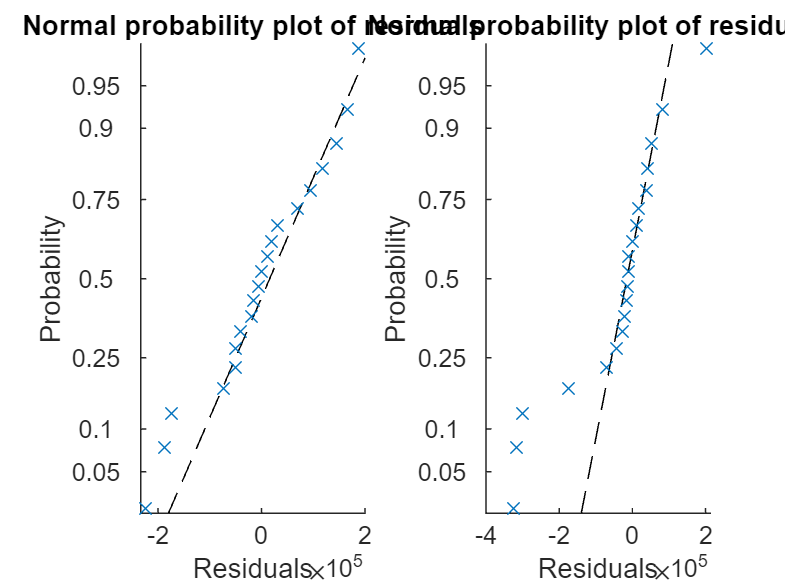

subplot(1,2,1)
plotResiduals(linearesModel, 'probability')
subplot(1,2,2)
plotResiduals(linearesModel_robust,'probability')